# Network and Graphical Models to Interpret the Set of Scores

AUTHOR: Kambadur Ananthamurthy

MAIN PROBLEM STATEMENT: Develop perspectives to understand the scores of the various methods.

close all
%clear

tic

input.nCells = 135;
input.nAlgos = 8;
input.nMethods = 6;

workingOnServer = 1;

if workingOnServer == 1 %Bebinca
    % Synthetic Dataset Details
    input.gDate = 20210824; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210918; %consolidation date
    input.cRun = 1; %consolidation run number
    
elseif workingOnServer == 2 %Adama
    % Synthetic Dataset Details
    input.gDate = 20210903; %generation date
    input.gRun = 1; %generation run number
    input.nDatasets = 333;
    
    % Consolidated Analysis Details
    input.cDate = 20210911; %consolidation date
    input.cRun = 1; %consolidation run number
end

workingOnServer = 0;
diaryOn         = 0;


% Directory config

if workingOnServer == 1
    HOME_DIR = '/home/bhalla/ananthamurthy/';
    saveDirec = strcat(HOME_DIR, 'Work/Analysis/Imaging/');
elseif workingOnServer == 2
    HOME_DIR = '/home/ananth/Documents/';
    HOME_DIR2 = '/home/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
else
    HOME_DIR = '/Users/ananth/Documents/';
    HOME_DIR2 = '/Users/ananth/Desktop/';
    saveDirec = strcat(HOME_DIR2, 'Work/Analysis/Imaging/');
end
%Additinal search paths
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/CustomFunctions')))
addpath(genpath(strcat(HOME_DIR, 'rho-matlab/localCopies')))
make_db

saveFolder = strcat(saveDirec, db.mouseName, '/', db.date, '/');

if diaryOn
    if workingOnServer == 1
        diary (strcat(HOME_DIR, '/logs/benchmarksDiary'))
    else
        diary (strcat(HOME_DIR2, '/logs/benchmarksDiary_', num2str(gDate), '_', num2str(gRun)))
    end
    diary on
end


% Operations
plotRefQ = 1;
plotAnalysedQs = 1;
plotDatasetCheck = 0;

% Synthetic Dataset Details
input.gDate = 20210824; %generation date
input.gRun = 1; %generation run number
input.nDatasets = 333;

% Consolidated Analysis Details
input.cDate = 20210918; %consolidation date
input.cRun = 1; %consolidation run number

workingOnServer = 0;
diaryOn         = 0;

% Load Synthetic Data
disp('Loading synthetic datasets ...')

Loading synthetic datasets ...


synthDataFilePath = sprintf('%s/synthDATA_%i_gRun%i_batch_%i.mat', ...
    saveFolder, ...
    input.gDate, ...
    input.gRun, ...
    input.nDatasets);
load(synthDataFilePath)
disp('... done!')

... done!


% Load Analysis Results
disp('Loading analysis results ...')

Loading analysis results ...


analysisFilePath = sprintf('%s/synthDATA_Analysis_%i_cRun%i_cData.mat', ...
    saveFolder, ...
    input.cDate, ...
    input.cRun);
load(analysisFilePath)
disp('... done!')

... done!



input.removeNaNs = 0;
input.saveFolder = saveFolder;


%Prepare the Look Up Table (LUT)
[response, predictor] = getTheTable(sdo_batch, cData, input);

Creating Look Up Table ...
... done!



%Normalize
maxima = max(predictor);
normPredictor = predictor./maxima;

%Z-Score
zPredictor = zscore(predictor);

% Normalize Z-Score
maxima = max(zPredictor);
nzPredictor = zPredictor./maxima;

% Preprocessing
Z = zPredictor(:, 1:5); % One can try using any of the other normalized or standardized versions

## Graphs

|======================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |  MinLeafSize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |
|======================================================================================|
|    1 | Best   |   0.0096319 |     0.22496 |   0.0096319 |   0.0096319 |           38 |
|    2 | Accept |    0.010566 |     0.18929 |   0.0096319 |    0.010099 |          429 |
|    3 | Best   |   0.0085419 |     0.24339 |   0.0085419 |   0.0095731 |            4 |
|    4 | Accept |    0.010566 |     0.15546 |   0.0085419 |   0.0085421 |         5876 |
|    5 | Best   |   0.0085196 |     0.27162 |   0.0085196 |   0.0085194 |            1 |
|    6 | Accept |   0.0086309 |     0.25479 |   0.0085196 |   0.0085503 |            2 |
|    7 | Accept |   0.0085196 |     0.27168 |   0.0085196 |     0.00852 |            1 |
|    8 | Accept |   0

Mdl =   ClassificationTree
                         ResponseName: 'Y'
                CategoricalPredictors: []
                           ClassNames: [0 1]
                       ScoreTransform: 'none'
                      NumObservations: 44955
    HyperparameterOptimizationResults: [1×1 BayesianOptimization]


  Properties, Methods


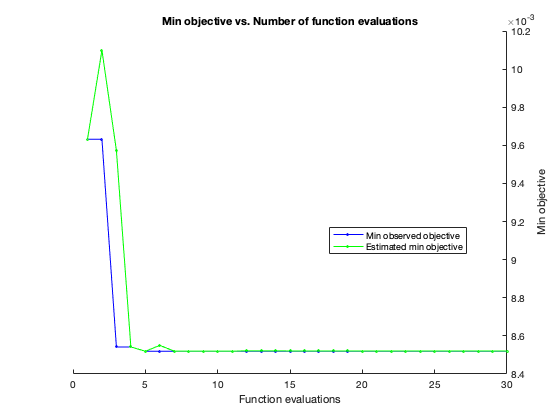

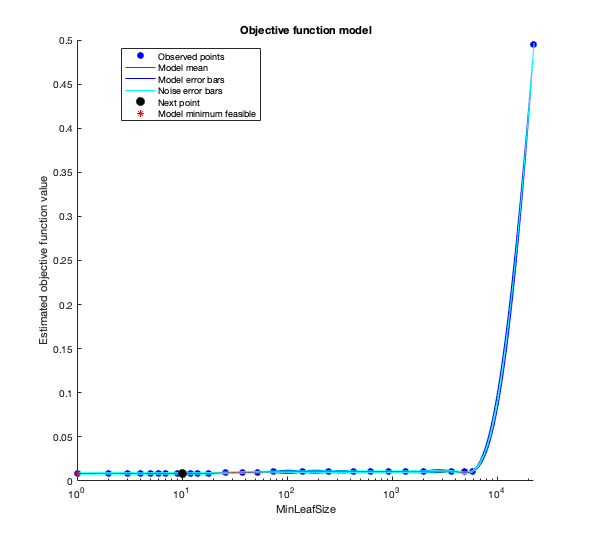

Mdl = fitctree(Z, response,'OptimizeHyperparameters','auto')

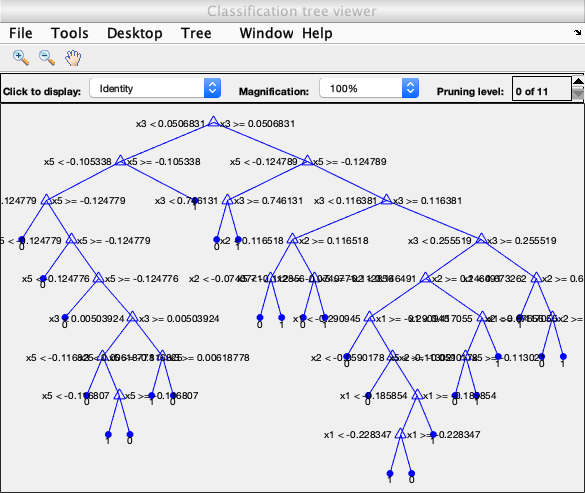

view(Mdl,'Mode','graph') %As a graph

%view(Mdl,'Mode','text') %As text


Decision tree for classification
 1  if x3<0.0506831 then node 2 elseif x3>=0.0506831 then node 3 else 1
 2  if x5<-0.105338 then node 4 elseif x5>=-0.105338 then node 5 else 0
 3  if x5<-0.124789 then node 6 elseif x5>=-0.124789 then node 7 else 1
 4  if x5<-0.124779 then node 8 elseif x5>=-0.124779 then node 9 else 0
 5  class = 1
 6  if x3<0.746131 then node 10 elseif x3>=0.746131 then node 11 else 0
 7  if x3<0.116381 then node 12 elseif x3>=0.116381 then node 13 else 1
 8  class = 0
 9  if x5<-0.124779 then node 14 elseif x5>=-0.124779 then node 15 else 0
10  class = 0
11  class = 1
12  if x2<0.116518 then node 16 elseif x2>=0.116518 then node 17 else 1
13  if x3<0.255519 then node 18 elseif x3>=0.255519 then node 19 else 1
14  class = 0
15  if x5<-0.124776 then node 20 elseif x5>=-0.124776 then node 21 else 0
16  if x2<-0.0740771 then node 22 elseif x2>=-0.0740771 then node 23 else 1
17  if x5<-0.112856 then node 24 elseif x5>=-0.112856 then node 25 else 0
18  if x2<0.146491 the